close all;
clc;

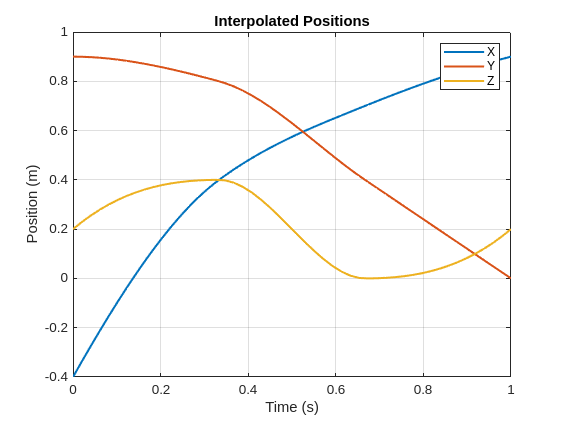

% Load UR5e robot
robot = loadrobot("universalUR5e");
robot.DataFormat = 'row';

% Add gripper (optional)
ur5e = exampleHelperAddGripper(robot);

% Home position
homePosition = deg2rad([-15, -126, 113, -80, -91, 76]);
for i = 1:6
    ur5e.Bodies{i+2}.Joint.HomePosition = homePosition(i);
end

% Inverse kinematics solver
ik = inverseKinematics('RigidBodyTree', ur5e);
weights = [1, 1, 1, 1, 1, 1];
initialGuess = homePosition;

% Define waypoints (control points)
timeWaypoints = linspace(0, 1, 4); % Time for each waypoint
waypoints = [ -0.4, 0.4, 0.7, 0.9;  % X positions
              0.9, 0.8, 0.4, 0.0;   % Y positions
              0.2, 0.4, 0.0, 0.2];  % Z positions

% Time vector for interpolation
numSamples = 50;
timeInterpolated = linspace(0, 1, numSamples);

% Perform cubic interpolation using 'pchip' for each row
interpolatedX = interp1(timeWaypoints, waypoints(1, :), timeInterpolated, 'pchip');
interpolatedY = interp1(timeWaypoints, waypoints(2, :), timeInterpolated, 'pchip');
interpolatedZ = interp1(timeWaypoints, waypoints(3, :), timeInterpolated, 'pchip');

% Combine interpolated points
interpolatedPoints = [interpolatedX; interpolatedY; interpolatedZ];

% Compute velocities and accelerations using finite differences
velocities = diff(interpolatedPoints, 1, 2) / (timeInterpolated(2) - timeInterpolated(1));
accelerations = diff(interpolatedPoints, 2, 2) / (timeInterpolated(2) - timeInterpolated(1))^2;

% Add zeros for first velocity and acceleration points
velocities = [zeros(3, 1), velocities];
accelerations = [zeros(3, 2), accelerations];

%% Plot position
figure;
plot(timeInterpolated, interpolatedPoints(1, :), 'LineWidth', 1.5);
hold on;
plot(timeInterpolated, interpolatedPoints(2, :), 'LineWidth', 1.5);
plot(timeInterpolated, interpolatedPoints(3, :), 'LineWidth', 1.5);
title('Interpolated Positions');
xlabel('Time (s)');
ylabel('Position (m)');
legend("X", "Y", "Z");
grid on;

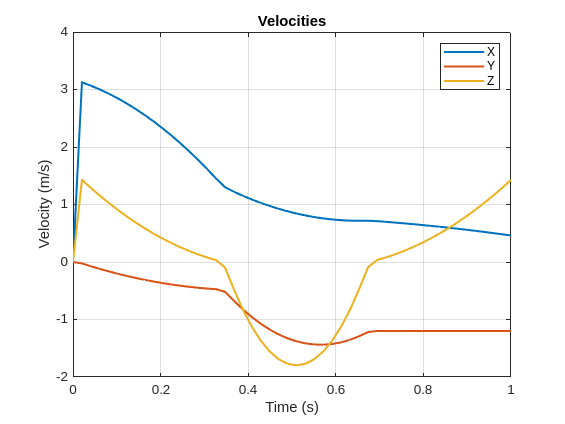


%% Plot velocity
figure;
plot(timeInterpolated, velocities(1, :), 'LineWidth', 1.5);
hold on;
plot(timeInterpolated, velocities(2, :), 'LineWidth', 1.5);
plot(timeInterpolated, velocities(3, :), 'LineWidth', 1.5);
title('Velocities');
xlabel('Time (s)');
ylabel('Velocity (m/s)');
legend("X", "Y", "Z");
grid on;

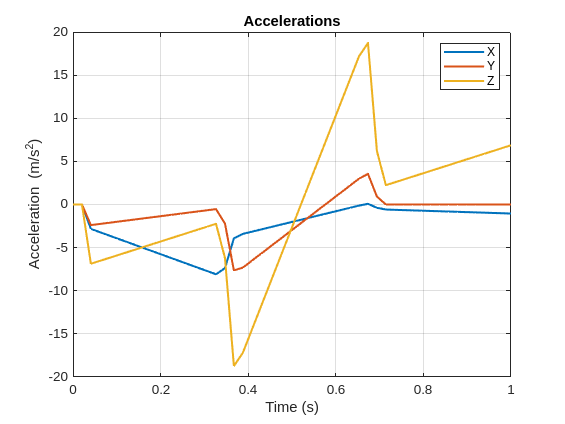


%% Plot acceleration
figure;
plot(timeInterpolated, accelerations(1, :), 'LineWidth', 1.5);
hold on;
plot(timeInterpolated, accelerations(2, :), 'LineWidth', 1.5);
plot(timeInterpolated, accelerations(3, :), 'LineWidth', 1.5);
title('Accelerations');
xlabel('Time (s)');
ylabel('Acceleration (m/s^2)');
legend("X", "Y", "Z");
grid on;

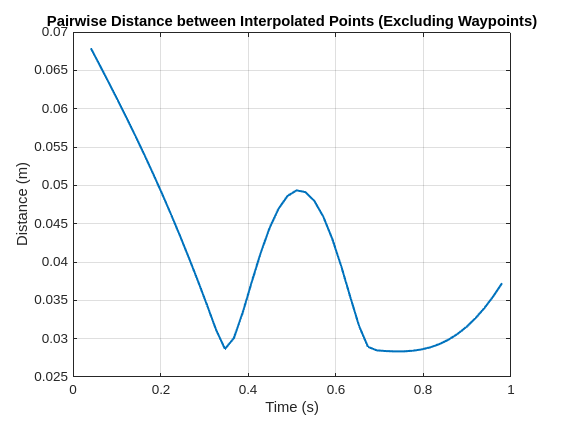

%% Exclude Waypoints for Pairwise Distance Calculation
% Mark the interpolated points that correspond to the waypoints
excludeControlPoints = false(size(interpolatedPoints, 2), 1);
for i = 1:size(waypoints, 2)
    for j = 1:size(interpolatedPoints, 2)
        % Check if the interpolated point matches the waypoint
        if all(abs(interpolatedPoints(:, j) - waypoints(:, i)) < 1e-6)
            excludeControlPoints(j) = true;  % Mark the waypoint to exclude
            break;
        end
    end
end

% Exclude the waypoints (control points) from the interpolated points
interpolatedPointsWithoutWaypoints = interpolatedPoints(:, ~excludeControlPoints);
timeInterpolatedWithoutWaypoints = timeInterpolated(~excludeControlPoints);

% Compute pairwise Euclidean distances (excluding the waypoints)
distances = sqrt(sum(diff(interpolatedPointsWithoutWaypoints, 1, 2).^2, 1));

% Plot pairwise distance between interpolated points (excluding waypoints)
figure;
plot(timeInterpolatedWithoutWaypoints(2:end), distances, 'LineWidth', 1.5);
title('Pairwise Distance between Interpolated Points (Excluding Waypoints)');
xlabel('Time (s)');
ylabel('Distance (m)');
grid on;

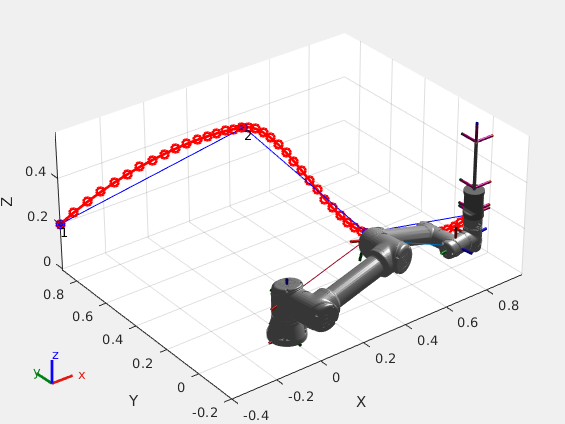

%% Visualize the robot's path and waypoints
figure;
show(ur5e, homePosition, 'Frames', 'on', 'PreservePlot', true);
hold on;

% Plot interpolated trajectory
plot3(interpolatedPoints(1, :), interpolatedPoints(2, :), interpolatedPoints(3, :), 'ro-', 'LineWidth', 2);

% Plot waypoints
plot3(waypoints(1,:), waypoints(2,:), waypoints(3,:), 'bo-', 'MarkerFaceColor', 'b');
text(waypoints(1,:), waypoints(2,:), waypoints(3,:), {'1','2','3','4'}, 'VerticalAlignment','top','HorizontalAlignment','left');

% Adjust robot and path visibility to fit the plot
axis([-0.5 1 -0.5 1 -0.2 0.6]);  % Set axis limits for a clear view
grid on;
axis equal;
view(3);

% Animate the Robot Motion and Adjust Z-Axis Dynamically
robotAnimation = VideoWriter('robot_animation.avi', 'Motion JPEG AVI');
open(robotAnimation);

% Initial Z limit
zMin = -0.2;
zMax = 0.6;

for i = 1:size(interpolatedPoints, 2)  % Loop through each interpolated point
    % Compute IK for the current position
    T = trvec2tform(interpolatedPoints(:, i)');  % Convert to homogeneous transformation
    [theta, ~] = ik('tool0', T, weights, initialGuess);  % Compute joint angles for the position
    
    % Update robot configuration
    show(ur5e, theta, 'Frames', 'on', 'PreservePlot', false);
    
    % Update Z axis dynamically based on the robot's current position
    currentZ = interpolatedPoints(3, i); % Z-coordinate of the robot's end effector
    
    % Modify Z limits to zoom out if the Z position is approaching the edge
    zMin = min(zMin, currentZ - 0.2); % Slight zoom-out in Z
    zMax = max(zMax, currentZ + 0.2); % Slight zoom-out in Z
    
    % Set updated axis limits
    axis([-0.5 1 -0.5 1 zMin zMax]);
    
    % Capture the frame for the animation
    frame = getframe(gcf);
    writeVideo(robotAnimation, frame);
    
    pause(0.1); % Adjust for smooth animation
end

% Close video file
close(robotAnimation);

% Adjust the plot to fit the robot and path
grid on;
axis equal;
view(3);